f = @(x) -12-21.*x+18.*x.^2-2.75.*x.^3;
fs = sym(f)

$$fs = -\frac{11\,x^{3}}{4}+18\,x^{2}-21\,x-12$$

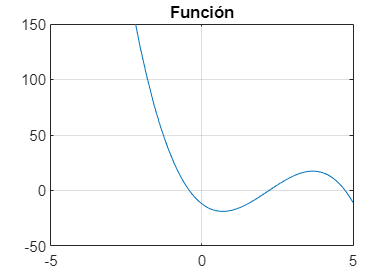

fplot(f)
title("Función")
xlim([-5, 5])
ylim([-50, 150])
grid on


a = -5;
b = 5;
[x0, it] = interpolacion(f, a, b)

x0 = 4.7403

it = 19

function [x,i]=interpolacion(f,a,b)
    i=0;
    iMAX=52;
    TolMax=eps;
    ban=true;
    fa=f(a);
    fb=f(b);
    while(ban)
        x=b-(a-b)/(fa-fb)*fb;
        fx=f(x);
        if(not(sign(fb)==sign(fx)))
            b=x;
            fb=fx;
        else
            a=x;
            fa=fx;
        end
        i=i+1;
        ban=abs(1-b/a)>TolMax&&i<iMAX;
    end
end 